%  the histogram of the random array in pdf format
clear; clc;

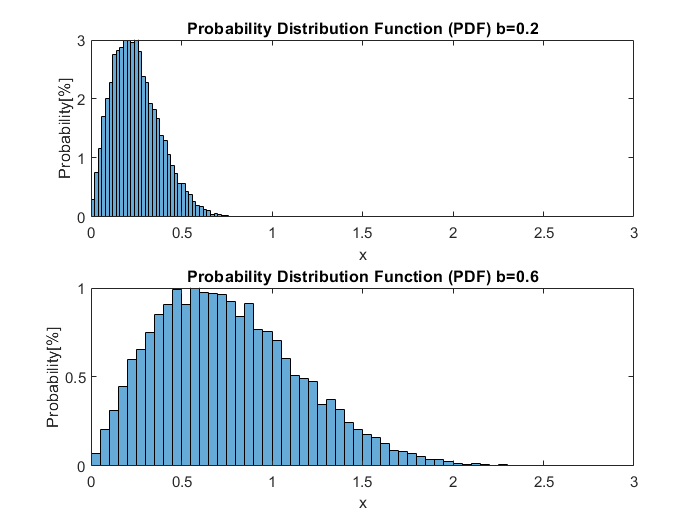

% using raylrnd.m
figure()
subplot(211)
A_02 = raylrnd(0.2, [1 10000]);
histogram(A_02, 'Normalization', 'pdf')
title("Probability Distribution Function (PDF) b=0.2")
xlabel('x');ylabel('Probability[%]');
axis([0 3 0 3])
subplot(212)
A_06 = raylrnd(0.6, [1 10000]);
histogram(A_06, 'Normalization', 'pdf')
title("Probability Distribution Function (PDF) b=0.6")
xlabel('x');ylabel('Probability[%]');
axis([0 3 0 1])

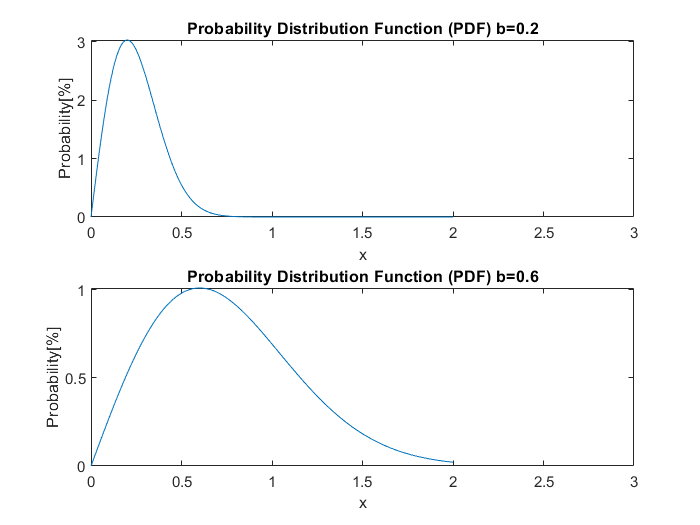

% using raylpdf.m
figure()
subplot(211)
B_02 = raylpdf([0:0.01:2],0.2);
plot([0:0.01:2], B_02)
title("Probability Distribution Function (PDF) b=0.2")
xlabel('x');ylabel('Probability[%]');
axis([0 3 0 max(B_02)])
subplot(212)
B_06 = raylpdf([0:0.01:2],0.6);
plot([0:0.01:2],B_06)
title("Probability Distribution Function (PDF) b=0.6")
xlabel('x');ylabel('Probability[%]');
axis([0 3 0 max(B_06)])

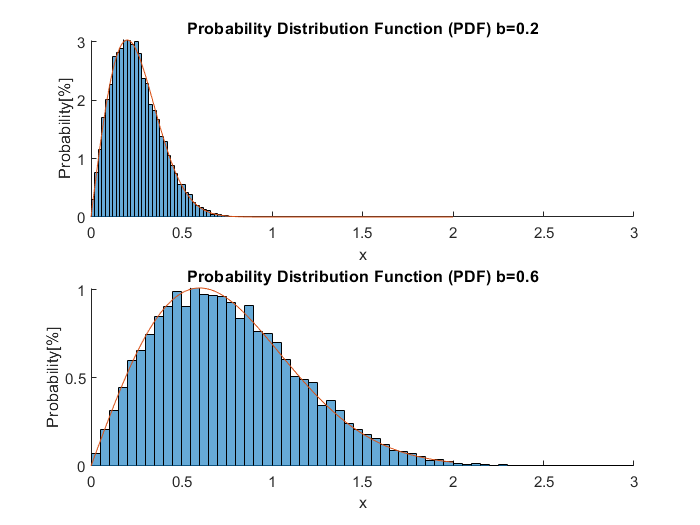

% combine the result of two ways
figure()
subplot(211)
hold on
histogram(A_02, 'Normalization', 'pdf')
plot([0:0.01:2], B_02)
title("Probability Distribution Function (PDF) b=0.2")
xlabel('x');ylabel('Probability[%]');
axis([0 3 0 max(B_02)])

subplot(212)
hold on
histogram(A_06, 'Normalization', 'pdf')
plot([0:0.01:2], B_06)
title("Probability Distribution Function (PDF) b=0.6")
xlabel('x');ylabel('Probability[%]');
axis([0 3 0 max(B_06)])